# Train, Evaluate, and Apply Image Category Classifier

Load two image categories.

%clear;
%clc;
% %setDir  = fullfile(toolboxdir('vision'),'visiondata','imageSets');
% imds = imageDatastore(fullfile('E:\STUDY','Semester 7', 'PA', 'dataset_1', 'tilesimage2\', {'Normal','Defect'}),...
% 'LabelSource', 'foldernames', 'FileExtensions', {'.png', '.jpeg', '.jpg'});
% imds.Labels
% %IncludeSubfolders',true,'LabelSource',...
%     %'foldernames');

Split the data set into a training and test data. Pick 30% of images from each set for the training data and the remainder 70% for the test data.

% [imds1,imds2] = splitEachLabel(imds,0.8,'randomize');

Create bag of visual words.

bag = bagOfFeatures(imds1)


Creating Bag-Of-Features.
-------------------------
* Image category 1: Defect

Train a classifier with the training sets.

categoryClassifier = trainImageCategoryClassifier(imds1,bag)

Evaluate the classifier using test images. Display the confusion matrix.

confMatrix = evaluate(categoryClassifier,imds2)

Find the average accuracy of the classification.

mean(diag(confMatrix))

Apply the newly trained classifier to categorize new images.

img = imread(fullfile('E:\STUDY\Semester 7\PA\dataset_1\tilesimage2\', '190.png'));
[labelIdx, score] = predict(categoryClassifier,img);
%v = VideoReader('E:\STUDY\Semester 7\PA\dataset_1\1\keramik1.MP4');
%frame = read(v,[1 Inf]);
%framegray = rgb2gray(frame);
%[labelIdx, score] = predict(categoryClassifier, framegray);

Display the classification label.

Result = categoryClassifier.Labels(labelIdx)

Result = 1×1 cell array
    {'Defect'}


%Result = categoryClassifier.Labels(labelIdx)
imshow(img)

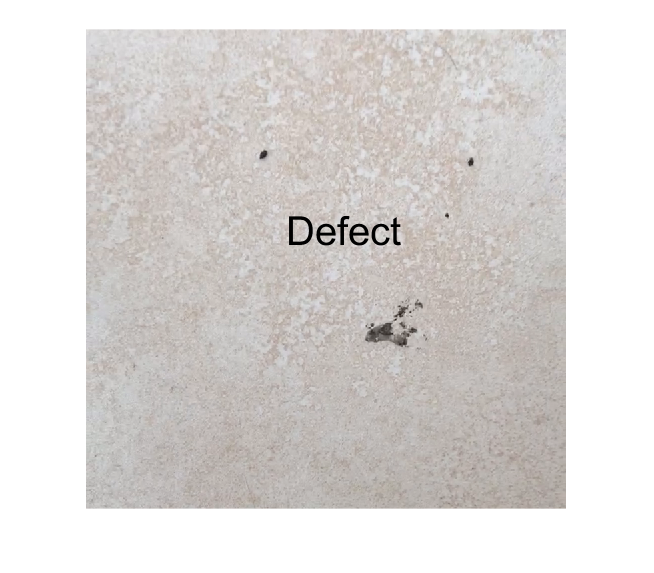

%imshow(frame)
hold on
text(300,300,Result, 'FontSize', 30)

*Copyright 2012 The MathWorks, Inc.*